## Lec 19 Voice Controlled Game Project Overview

Goal: Design a vowel-controlled game in two steps: First, a system that works robustly, Second, the system is optimized by making signal processing more efficient.

- Tic-Toc on PC performance measure normalizes the time criterion.

- The game now has three levels +dy, 0, -dy. Random Control give example.

- Vowel control requires templates (See Lec 18 for Robust system templates)

- The Optimized system gives comparable performance as the Robust system but with more efficient signal processing (less time).

- The variables to be reduced for the Optimized system are recTime (length of voice recording) and Nx (size of signal for processing)

- Level of required code comments in your code is given in the code below.

- Points for each problem are given in parentheses.

- Include your name on submitted project file to simplify grading.

#### PC Benchmark performance measure

clear
tic % reset clock 
nTrials = 100; %do something 100 times and keep track of tic toc value
CPU_time = zeros(1,nTrials);
for trial = 1:nTrials  % repeat to get a distribution
    for i = 1:1000    
        X = abs(fft(randn(1,1000)));  % a typical task in this project
    end
    CPU_time(trial) = toc;  % gives time from previosu tic
    tic % reset clock
end
hist(CPU_time)
max_CPU_time = max(CPU_time)

max CPU_time = 0.0643.

#### System initialization

**(1) SI1. What the parameters and their sizes that need to be loaded into memory for the Robust system?** The parameters are Hi and Ha which are the magnitudes (Hmag) that will be used to form the template for /e/ and /a/ respectively. The sizes of Hi and Ha are both 1000 in length. The size of Ta and Ti arrays are 501 in length. Other parameters include hw (array of our hamming window) with size 1000, recTime (a number), and I also added a parameter, the transient, which is the lag that comes from the microphone system when you record using matlab. 

**(1) SI2. What is the initialization time for Robust sytem?** 0.065s

**(2) SI3. How did you convert Hmags into the normalized templates Ta and Ti for template matching?** From Hmag, I first subsetted the array from 1:501 to get the right template size. Then, I subtracted the template by its mean and then divided it by its standard deviation to normalize it. 

**(1) SI4. What the parameters and their sizes that need to be loaded into memory for the Optimized system? **I first load the filter coefficients (3x2 matrix), separated each row into three separate variables, which I use to make my Hmags for /e/ and /a/, which has size 700. From there, I can make my template for /e/ and /a/ respectively. The sizes of the templates Ti and Ta are 351 in length. Other parameters include hw (array of our hamming window) with size Nx, recTime (a number), and I also added a parameter, the transient, which is the lag that comes from the microphone system when you record using matlab. 

**(1) SI5. What is the initialization time for Optimized sytem?** 0.075s

**(5)  SI6. How did you convert the Optimized system parameters into the normalized templates Ta and Ti for template matching?** I first made Ha and Hi by running 3 AR filters using each row of the filter coefficient matrix (a = [ 2*r*cos(omega_o) -r^2]) and a unit response with size nx sequence as input and taking the fft of the output, I then normalized Hmag (see helper function getHmag). I got the templates (since I changed Nx) by sub-segmenting Ha and Hi from 1:Nx/2+1. Then, I subtracted the two template by its mean and then divided it by its standard deviation to normalize it. 

#### Speech Acquisition  

**(1) SA1. Robust system recTime value **= 0.5s.

**(1) SA2. Optimized system recTime value **= 0.19s

**(2) SA3. How did you determine the rectime value for the Optimized system?** my earbud's microphone has a transient of ~800 (1/8 of a second). The game system can robustly tolerate a Nx=700. I fixed the Nx value and decreased recTime until PE>0. I found that at recTime  ~ 0.19s, the PE was 0, and it became non-zero when I decreased recTime to 0.18. 

**(1) SA4. Robust system Nx value = **1000.

**(1) SA5. Optimized system Nx value =** 700.

**(2) SA6. How did you determine the Nx value for the Optimized system?** The lower the Nx is better, so I decreased the Nx until there were substantial error in the game (so for instance, the point repeatedly goes up when I say /a/). I found that for Nx = 700, I was able to get a low probability of error (see code section below). (When I used Nx = 600 and recTime = 0.18s, I got PE = 0.5)

**(1) SA7. What does your program do if you don't say anything?** Nothing happens, the dot doesn't move up or down vertically but keeps approaching the target horizontally. 

**(4) SA8. Compose a code section that helps determine recTime and Nx values.** 

How this code section works is that it prompts you to keep singing /a/ or /e/ until it prompts you to stop. WIthin that time, the system takes 5 samples signals (with predetermined recTime and Nx) of each of /a/ and /e/ and run it through template matching. It then calculates the probability of error by adding the number of errors (ex. If an /a/ was identified as an /e/, where Vi > Va) and dividing it by 10. **Note you have to say something for this code to work!! **It is an estimate of PE to allow us to gage around where the Nx and Rectime should be around using an analysis somewhat similar to monte carlo. 

clear; clf; format compact;

This code help you measure the transient

transient = getTransient
recObj = audiorecorder(8000,8,1); %use get speech
dummy=1;

Press any key to start recording, say anything for 1s
Start speaking now
End of recording


transient = 795

%finding appropriate Nx: this code finds the lowest that Nx can go without
%significant padding  to be able to distinguish /a/ and /e/
while dummy==1; % ctrl-c to exit
    Nx = input('Nx: '); %INPUT NX
    recTime = (Nx+transient)/8000; %input rectime
    testNx(Nx,recTime,recObj, transient) %see helper function 
    dummy=input('1 to continue, 0 to stop ');
end
dummy=1;
%finding appropriate recTime: this portion of the code allows you to find

For the next 5 seconds keep saying /a/ until prompted to stop
Press any key to start recording
stop
For the next 5 seconds keep saying /e/ until prompted to stop
Press any key to start recording
stop


recTime = 0.1619

nx = 500

PE = 0.4000

For the next 5 seconds keep saying /a/ until prompted to stop
Press any key to start recording
stop
For the next 5 seconds keep saying /e/ until prompted to stop
Press any key to start recording
stop


recTime = 0.1744

nx = 600

PE = 0.5000

For the next 5 seconds keep saying /a/ until prompted to stop
Press any key to start recording
stop
For the next 5 seconds keep saying /e/ until prompted to stop
Press any key to start recording
stop


recTime = 0.1869

nx = 700

PE = 0

%the lowest rectime by fixing Nx to be able to distinguish /a/ and /e/
while dummy==1; % ctrl-c to exit
    Nx = 700; %INPUT NX
    recTime = input('recTime: '); %input rectime
    testNx(Nx,recTime,recObj, transient) %see helper function 
    dummy=input('1 to continue, 0 to stop ');
end

For the next 5 seconds keep saying /a/ until prompted to stop
Press any key to start recording
stop
For the next 5 seconds keep saying /e/ until prompted to stop
Press any key to start recording
stop


recTime = 0.1900

nx = 700

PE = 0

For the next 5 seconds keep saying /a/ until prompted to stop
Press any key to start recording
stop
For the next 5 seconds keep saying /e/ until prompted to stop
Press any key to start recording
stop


recTime = 0.1800

nx = 700

PE = 0.1000

Plotting what a sample input signal would look like:

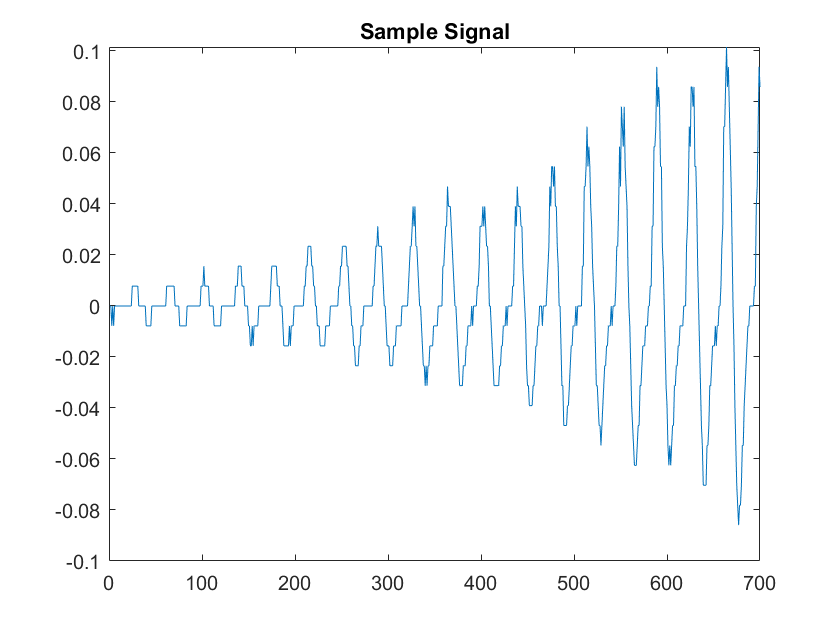

recTime=0.19;
Nx=700;
x = getSpeech(recObj,recTime,Nx,transient);
plot(x)
title("Sample Signal")

#### Signal processing

**(1) SP1. Why is the denominator in Hamming data window cosine argument equal to (Nx-1) and not Nx?** Because otherwise we won't be able to get a full period of cosine + 1 additional point (we want that symmetry property of cosine), since we start the input into cosine at 0, so we must incrementally increase the inputs by $2\pi/{(Nx-1)}$to get a full period +1 additional point. 

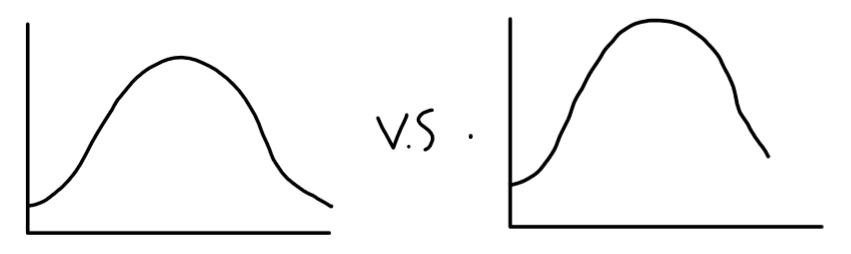(you want the first one and not the second one to preserve the symmetry of the cosine)

**(1) SP2. What parameters does the Robust system load that help classify the acquired speech signal?** The two templates, Ta and Ti allow us to perform template matching on the normalized magnitude of the speech input after fourier transform. 

**(1) SP3. What parameters does the Optimized system load that help classify the acquired speech signal? **The two templates, Ta and Ti (made from the filter coefficients) allow us to perform template matching on the normalized magnitude of the speech input after fourier transform. 

**(1) SP4. Why is the denominator in Hamming data window cosine argument equal to (Nx-1) and not Nx?** Because otherwise we won't be able to get a full period of cosine (we want that symmetry property of cosine), since we start the input into cosine at 0, so we must incrementally increase the inputs by $2\pi/{(Nx-1)}$to get a full period inclusive. 

(you want the first one and not the second one to preserve the symmetry of the cosine)

**(1) SP5. What is the value of Nx, the length of the FFT input in the Robust system?** 1000.

**(3) SP6. Why can Nx in SP2 be reduced and still give good performance?** Nx determines the number of samples that we take out of our input signal. If we look at an unit response input, if nx is large, a lot of the points are redundant as by a certain point, you can replace the remainder of the input with zeros and won't be able to tell the difference. By decreasing Nx, the sample we use in the fft is smaller, i,e, a smaller hamming window, but it is still possible to perform template matching, although the tradeoff is that the accuracy of the classfication goes down (Law of large numbers). 

**(2) SP7.  How are the values for recTime and Nx related?** recTime determines the maximum length of the input signal, for example 0.5s would produce 4000 data points. Nx, on the other hand, is the length of the FFT input, which is cropped from the input signal through a hamming window or simply cropping the input signal. They don't have too much relation to each other because you could always pad the input signal with 0s if length(input signal) < Nx, or crop the input signal if Nx < length(input signal). Ideally, you don't crop the input signal because you are wasting data points that could give you more information. Thus, recTime*8000-transient should ideally be less than Nx. 

**(10) SP8. Compose a code section that helps determine the Nx value from the filter coefficients by displaying the resulting Ta and Ti templates. This can help to implement a helper function for the Optimized system. **

Templates for /i/ varying Nx

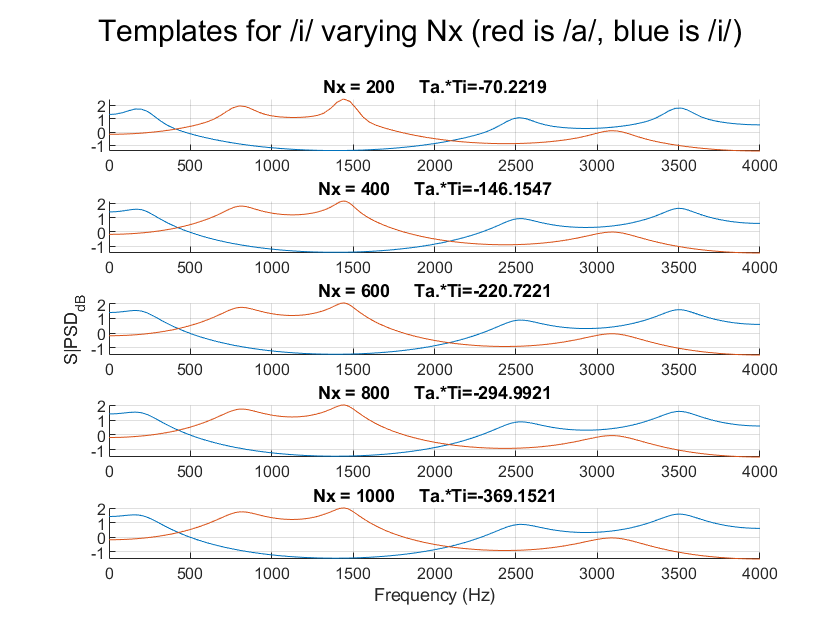

clear
clc
clf
% load filter coefs from Lec 19 HW for optimized system
load('a_filter','FilterCoefs')
a_coefs = FilterCoefs;
load('i_filter','FilterCoefs')
i_coefs = FilterCoefs;

figure
sgtitle('Templates for /i/ varying Nx (red is /a/, blue is /i/)') 
z=1;
for i = 200:200:1000
    subplot(5,1,z)
    hold on 
    Tea = plotSynthetic(i,i_coefs);
    Tei = plotSynthetic(i,a_coefs);
    temsum = sum(Tea.*Tei);
    num = strcat("Nx = ",num2str(i), "     Ta.*Ti=", num2str(temsum));
    title(num)
    hold off
    z=z+1;
end

As you can see, the convolution of each template gets smaller and smaller as Nx decreases. I chose an Nx of 700, because it seemed the differences between the template seemed robust. 

#### System comparison.  

**(1) SC1.  What is the length of the templates Ta and Ti in the Robust system?** 501

**(2) SC2.  What is the length of the templates Ta and Ti in the Optimized system?** 351

**(1) SC3. What is the number of wins in the Robust system?** 10

**(2) SC4. What is the number of wins in the Optimized system? **10

**(1) SC5. What is the time to finish 10 games in the Robust system? **197s

**(1) SC6. What is the time to finish 10 games in the Optimized system? **121s

#### Robust system program

**(20) RSP 1. Complete the code below and in the helper functions  to implement a working Robust system. After your Robust system works reliably, copy this code into the Optimized system program below and make the changes in that program.**

clear; clc; clf; format compact;
control = input('System (0=random)(1=robust)(2=optimized) ');

% initialization
tic % reset clock
recObj = audiorecorder(8000,8,1);

transient=800;
% load Hmag_dB for /a/ and /i/ from Lec 17 HW
load('aLP_Hmag.mat','Hmag_dB')
Ha = Hmag_dB;  % /a/
load('iLP_Hmag.mat','Hmag_dB')
Hi = Hmag_dB;  % /i/

switch control
    case 0
        Nx=1000;
    case 1
        str = 'Robust system ';
        Nx=1000;
        recTime = (Nx+transient)/8000; % record time in seconds
    case 2
        str = 'Optimized system ';
        Nx=700;
        recTime=(Nx+transient)/8000;
        load('a_filter','FilterCoefs')
        a_coefs = FilterCoefs;
        load('i_filter','FilterCoefs')
        i_coefs = FilterCoefs;

        % Get Hmag_dB for /a/ and /i/
        Ha=getHmag(Nx,a_coefs);
        Hi=getHmag(Nx,i_coefs);
end
      % length of signal x and H_mag
% define Hamming window of length Nx
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));


% Add code to define and normalize condition templates Ta and Ti. Normalize
% with respect to mean and STD. You need to cut the templates before the fft()
Ta = Ha(1:Nx/2+1);
Ti = Hi(1:Nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
Ti = Ti - mean(Ti); Ti = Ti/std(Ti);

nGames = 10; % increase to 10 after debugged
nWins = 0;
dx = 2;  % me_x and targetx increment, increasing dx makes game faster (bigger steps)  dx >= 1
dy = 3;  % me_y control increment
initTime = toc  % get initialization time

initTime = 0.0734

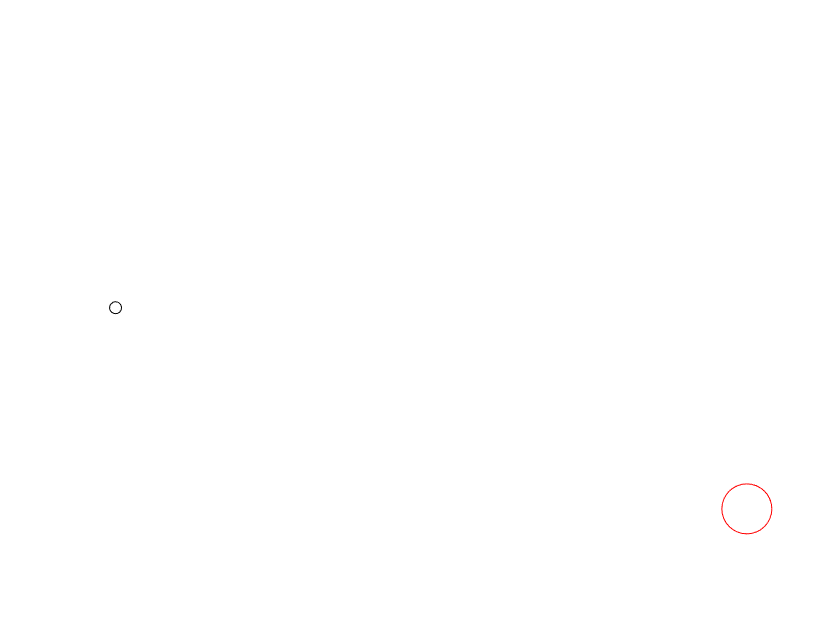

Game 1 / 10 WIN
Game 2 / 10 WIN
Game 3 / 10 WIN
Game 4 / 10 WIN
Game 5 / 10 WIN
Game 6 / 10 WIN
Game 7 / 10 WIN
Game 8 / 10 WIN
Game 9 / 10 WIN


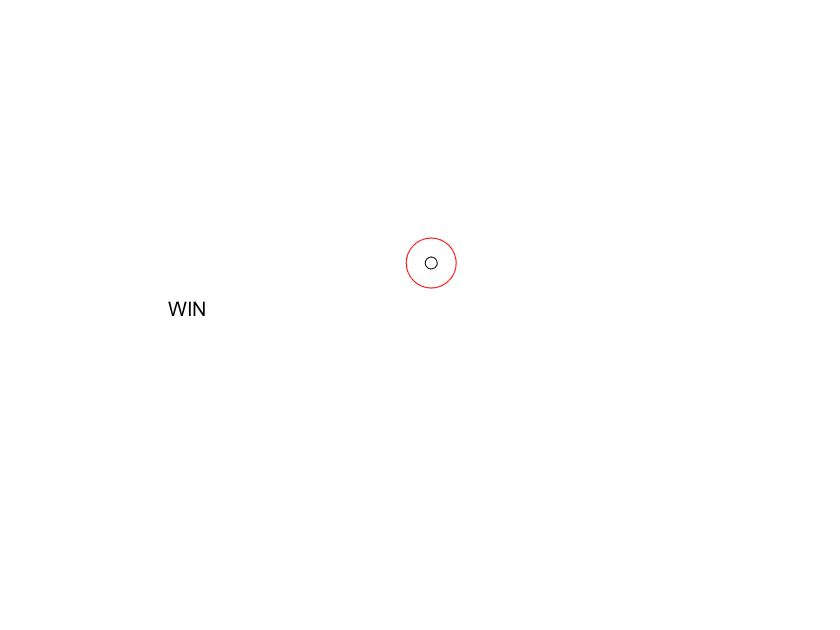

Game 10 / 10 WIN


tic % reset clock
for game = 1:nGames
    % initial locations
    targetx = 100;%right side this is the x axis, how fast it moves
    targety = randi([1,70]);  % on right side at random height
    me_x = 1; %me_y=35;
    me_y = randi([1,70]); % on left side at random height
    
    for n = 2:dx:100 %dx is how fast things move
        targetx = 100-n;
        me_x = n;      
        switch control
            case 0
                str = 'Random system';  % demonstration program
                me_y = targety + 2*randn();
                me_y = RandomSys(me_y,dy);
            case 1
                str = 'Robust system ';
                me_y = RobustSys(me_y,dy,recObj,recTime,Ta,Ti,hw,transient);
            case 2
                str = 'Optimized system ';
                me_y = OptimizedSys(me_y,dy,recObj,recTime,Ta,Ti,hw, transient);
        end
        
        [done, win, result] = displayGame(targetx,targety,me_x,me_y);
        if done == 1
            nWins = nWins + win;
            fprintf('Game %d / %d %s\n',game,nGames,result)
            break
        end
    end
    
end

fprintf('%s  %d wins in %d games\n',str,nWins,nGames)

Robust system   10 wins in 10 games


gTime = toc;
fprintf('Total time= %.2f seconds\n',gTime)

Total time= 196.97 seconds


#### Optimized system program

**(2) OSP1: What was changed from the Robust system to implement the working Optimized system?** recTime and Nx

**(2) OSP2: List the helper functions that were added. ** y = AR(a,x,ny), dummy = plotSynthetic(nx, a_coefs), games = testNx(Nx, recTime, recObj), and OptimizedSys(me_y,dy,recObj,recTime,Ta,Ti,hw), and getHmag(Nx,a_coefs)

**(24) OSP3: Paste the working Robust system program here and make changes to implement the working Optimized system. DO NOT CHANGE HELPER FUNCTIONS.  Add functions with prefix "Opt_"  to implement Optimized system. **I also included the .m script for the optimized system in my canvas submission. You can run the game by typing OptimizedSystem in the Command Window. This will allow the game to pop up in a separate window instead of in the live script. 

clear; clc; clf; format compact;
disp("Optmized voice controlled game. Press any key to start")

Optmized voice controlled game. Press any key to start


pause
% initialization
tic % reset clock
recObj = audiorecorder(8000,8,1);

str = 'Optimized system ';
Nx=700;
transient=800;
recTime=0.19;


% load filter coefs from Lec 19 HW for optimized system
load('a_filter','FilterCoefs')
a_coefs = FilterCoefs;
load('i_filter','FilterCoefs')
i_coefs = FilterCoefs;

% load Hmag_dB for /a/ and /i/ from Lec 17 HW
Ha=getHmag(Nx,a_coefs);
Hi=getHmag(Nx,i_coefs);


      % length of signal x and H_mag
% define Hamming window of length Nx
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));

% Add code to define and normalize condition templates Ta and Ti. Normalize
% with respect to mean and STD. 
Ta = Ha(1:Nx/2+1);
Ti = Hi(1:Nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
Ti = Ti - mean(Ti); Ti = Ti/std(Ti);

nGames = 10; % increase to 10 after debugged
nWins = 0;
dx = 2;  % me_x and targetx increment, increasing dx makes game faster (bigger steps)  dx >= 1
dy = 3;  % me_y control increment
initTime = toc  % get initialization time

initTime = 0.0654

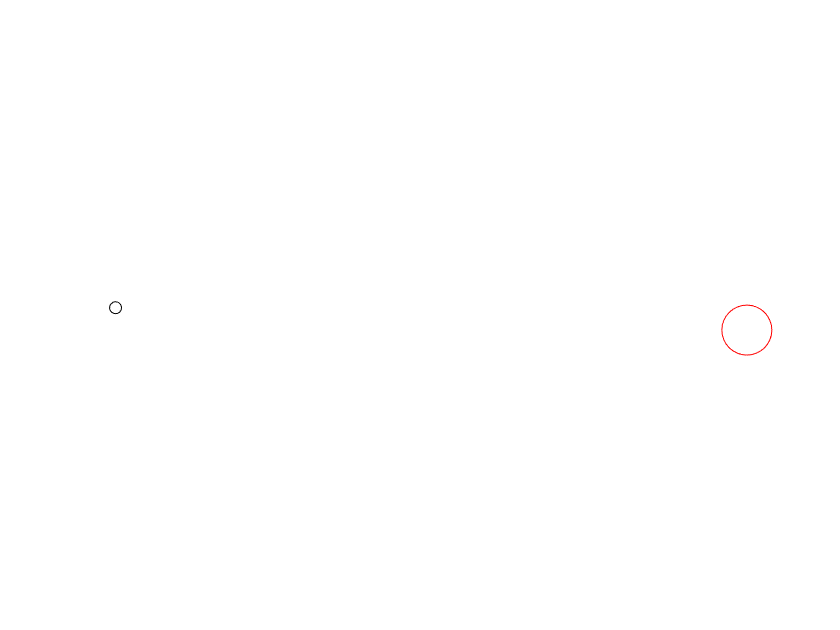

Game 1 / 10 WIN
Game 2 / 10 WIN
Game 3 / 10 WIN
Game 4 / 10 WIN
Game 5 / 10 WIN
Game 6 / 10 WIN
Game 7 / 10 WIN
Game 8 / 10 WIN
Game 9 / 10 WIN


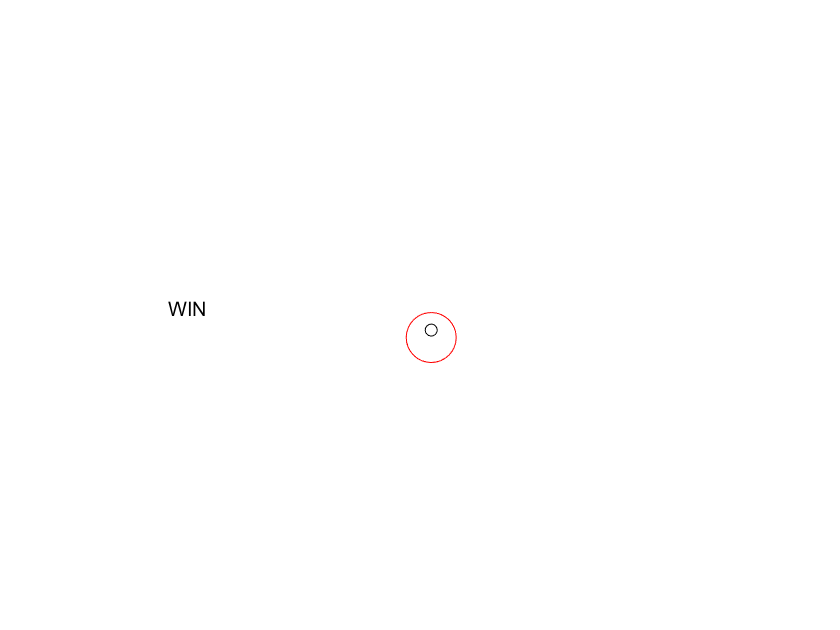

Game 10 / 10 WIN


tic % reset clock
for game = 1:nGames
    % initial locations
    targetx = 100;%right side this is the x axis, how fast it moves
    targety = randi([1,70]);  % on right side at random height
    me_x = 1; %me_y=35;
    me_y = randi([1,70]); % on left side at random height
    
    for n = 2:dx:100 %dx is how fast things move
        targetx = 100-n;
        me_x = n;
        me_y = OptimizedSys(me_y,dy,recObj,recTime,Ta,Ti,hw,transient);
        [done, win, result] = displayGame(targetx,targety,me_x,me_y);
        if done == 1
            nWins = nWins + win;
            fprintf('Game %d / %d %s\n',game,nGames,result)
            break
        end
    end
end

fprintf('%s  %d wins in %d games\n',str,nWins,nGames)

Optimized system   10 wins in 10 games


gTime = toc;
fprintf('Total time= %.2f seconds\n',gTime)

Total time= 121.05 seconds


**Optimized Program prototype 2 - changing how the template matching is interpreted**

After running the program multiple times, I found that the /a/ sounds had much less errors compared to /e/ sounds.This led me to investigate why this was the case. Turns out, when I ran template matching on /e/ and /a/ sounds, the difference between the template matching value Va and Vi were much bigger when it was an /a/ sound than when it was an /e/ sound. Sometimes Va was marginally bigger than Vi when it was an /e/ sound. Thus, instead of interpreting Va and Vi by comparing which is bigger, I set an interval of which if |Vi - Va| < 45, it will categorize as an /e/, and if Va > Vi + 50, it will be an /a/. (Keep in mind that these bounds work for my microphones, but a different microphone might have different Vi-Va bounds for this to work). 

In this prototype 2 of the optimized program, the initialization time is 0.078s, the time it took to complete the game was 110 seconds, and Nx was reduced to a size of 400! 

clear; clc; clf; format compact;
fprintf("Optmized voice controlled game. Press any key to start")

Optmized voice controlled game. Press any key to start

pause
% initialization
tic % reset clock
recObj = audiorecorder(8000,8,1);

str = 'Optimized system ';
Nx=400

Nx = 400

transient=800;
recTime=0.15;


% load filter coefs from Lec 19 HW for optimized system
load('a_filter','FilterCoefs')
a_coefs = FilterCoefs;
load('i_filter','FilterCoefs')
i_coefs = FilterCoefs;

% load Hmag_dB for /a/ and /i/ from Lec 17 HW
Ha=getHmag(Nx,a_coefs);
Hi=getHmag(Nx,i_coefs);


      % length of signal x and H_mag
% define Hamming window of length Nx
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));

% Add code to define and normalize condition templates Ta and Ti. Normalize
% with respect to mean and STD. 
Ta = Ha(1:Nx/2+1);
Ti = Hi(1:Nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
Ti = Ti - mean(Ti); Ti = Ti/std(Ti);

nGames = 10; % increase to 10 after debugged
nWins = 0;
dx = 2;  % me_x and targetx increment, increasing dx makes game faster (bigger steps)  dx >= 1
dy = 3;  % me_y control increment
initTime = toc  % get initialization time

initTime = 0.0766

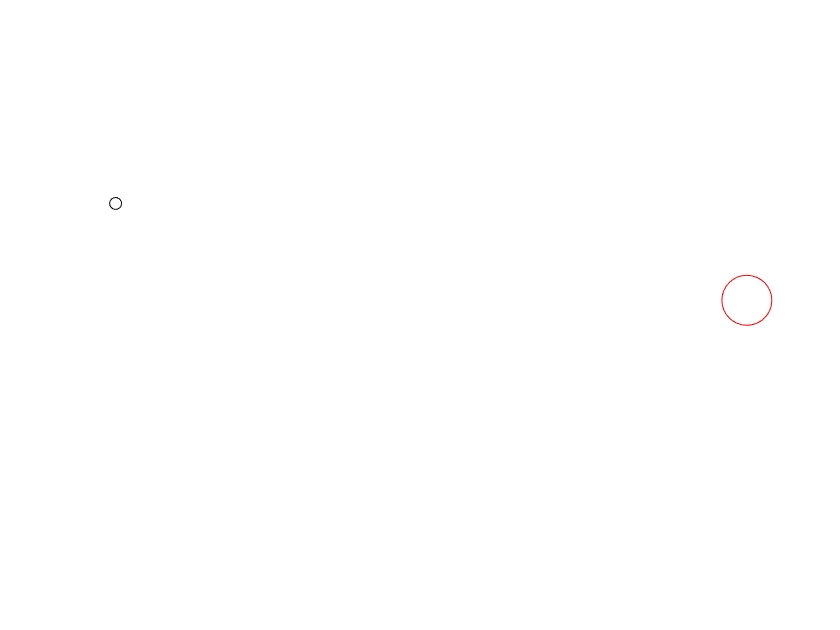

Game 1 / 10 WIN
Game 2 / 10 WIN
Game 3 / 10 WIN
Game 4 / 10 WIN
Game 5 / 10 WIN
Game 6 / 10 WIN
Game 7 / 10 WIN
Game 8 / 10 WIN
Game 9 / 10 WIN


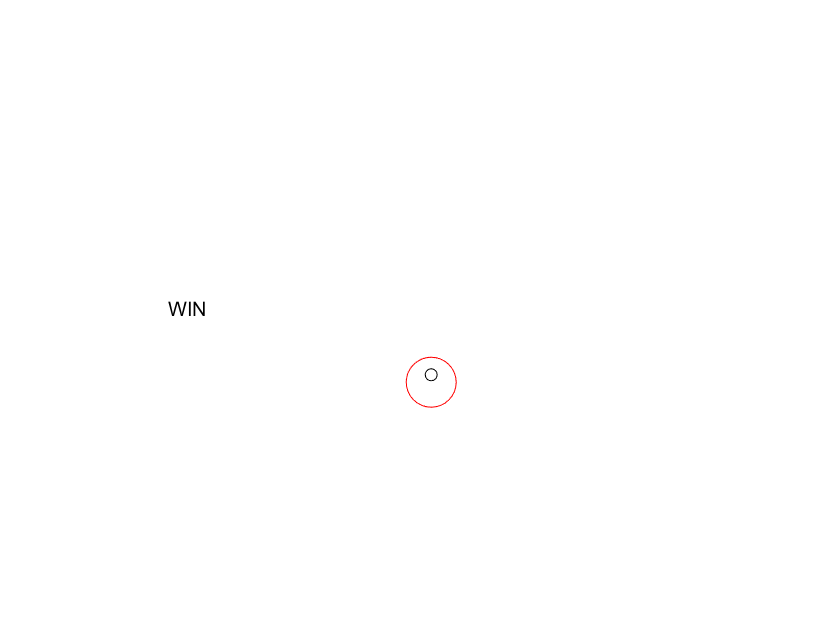

Game 10 / 10 WIN


tic % reset clock
for game = 1:nGames
    % initial locations
    targetx = 100;%right side this is the x axis, how fast it moves
    targety = randi([1,70]);  % on right side at random height
    me_x = 1; %me_y=35;
    me_y = randi([1,70]); % on left side at random height
    
    for n = 2:dx:100 %dx is how fast things move
        targetx = 100-n;
        me_x = n;
        me_y = OptimizedSys1(me_y,dy,recObj,recTime,Ta,Ti,hw,transient);
        [done, win, result] = displayGame(targetx,targety,me_x,me_y);
        if done == 1
            nWins = nWins + win;
            fprintf('Game %d / %d %s\n',game,nGames,result)
            break
        end
    end
end

fprintf('%s  %d wins in %d games\n',str,nWins,nGames)

Optimized system   10 wins in 10 games


gTime = toc;
fprintf('Total time= %.2f seconds\n',gTime)

Total time= 109.96 seconds


#### Helper functions

function x = getSpeech(recObj,recTime,Nx,transient)
    tau = 0.001;
    recordblocking(recObj, recTime);    %recTime is the variable we have to figure out. Its in the code 
    signal = getaudiodata(recObj)';
    x = signal(transient:end); % eliminates start transient for laptop mic
    x=signal(transient:end);
    if max(abs(x(1:100))) < tau % no speech at beginning
        x = zeros(1,Nx);
        return % exit function
    end
    nx = length(x);
    if nx < Nx
        x = [x zeros(1,Nx-nx)];
    else
        x = x(1:Nx);
    end
end
 
function me_y = RandomSys(me_y,dy)
R = randn(); %gaussian randn
if abs(R) <= 0.15 % me_y does not change
    return
end
if R > 0.15 && me_y < 70 % increase me_y if R>0.15 and me_y is not at top
    me_y = me_y + dy;
end
if R < -0.15 && me_y > 1  % decrease me_y if R<-0.15 and me_y is not at bottom
    me_y = me_y - dy;
end
pause(.2) % models processing delay. Introduce delay to model my processing time 
end


function me_y = RobustSys(me_y,dy,recObj,recTime,Ta,Ti,hw,transient)
myData = getSpeech(recObj,recTime,length(hw),transient);
x = myData;
nx = length(fft(hw.*x));
Xmag = abs(fft(hw.*x));
S_dB = 20*log10(Xmag);
S_dB = S_dB - max(S_dB);
S = S_dB(1:nx/2+1);
S = S - mean(S);
S = S/std(S);
Va = sum(Ta.*S);
Vi = sum(Ti.*S);
if Vi > Va +10
    me_y = me_y + dy;
elseif Va > 10 + Vi
    me_y = me_y - dy;
end
end




function me_y = OptimizedSys(me_y,dy,recObj,recTime,Ta,Ti,hw,transient)
myData = getSpeech(recObj,recTime,length(hw),transient);
x = myData;
nx = length(fft(hw.*x));
Xmag = abs(fft(hw.*x)); %getting the magnitude by applying hamming window and then fourier transform on our input
S_dB = 20*log10(Xmag);
S_dB = S_dB - max(S_dB); %normalize to 0dB
S = S_dB(1:nx/2+1);
S = S - mean(S);
S = S/std(S); %normalizing the input signal
Va = sum(Ta.*S);%template matching
Vi = sum(Ti.*S);
%depending on if Va is bigger or if Vi is bigger, add or subtract one from
%the y value of the moving dot 
if Vi > Va
    me_y = me_y + dy; 
elseif Va > 20 + Vi
    me_y = me_y - dy;
end
end


function me_y = OptimizedSys1(me_y,dy,recObj,recTime,Ta,Ti,hw,transient)
myData = getSpeech(recObj,recTime,length(hw),transient);
x = myData;
nx = length(fft(hw.*x));
Xmag = abs(fft(hw.*x));
S_dB = 20*log10(Xmag);
S_dB = S_dB - max(S_dB);
S = S_dB(1:nx/2+1);
S = S - mean(S);
S = S/std(S);
Va = sum(Ta.*S);
Vi = sum(Ti.*S);
if Vi > Va
    me_y = me_y + dy;
elseif abs(Vi-Va)<45
    me_y = me_y + dy;    
elseif Va-Vi>45
    me_y = me_y - dy;
end
end

 
function [done,win,result] = displayGame(tx,ty,mx,my)
done = 0;
win = 0;
result = 'Playing';
figure(1)
plot(tx,ty,'ro','markersize',25)
axis([1 100 1 70])
axis off
hold on
plot(mx,my,'ko')
hold off
if mx >= tx % reached target
    done = 1;
    result = 'LOSS';
    if abs(my-ty) < 4
        result = 'WIN';
        win = 1;
    end
    text(10,35,result)
    pause(1)
end
end


function y = AR(a,x,ny)
ybuf = zeros(size(a));  % output buffer memory
y = zeros(1,ny); % length of AR output is infinite, finite number must be specified.
for i = 1:length(y)  
    if i > length(x)
        xin = 0; 
    else
        xin = x(i);
    end
    y(i) = sum(a.*ybuf) + xin;  % sum of products
    % shift values in xbuf by one unit
    if length(ybuf) >= 2
        ybuf(2:length(ybuf)) = ybuf(1:length(ybuf)-1);
    end
    ybuf(1) = y(i);    
end
end

function dummy = plotSynthetic(nx, a_coefs)
fs = 8000; Ts = 1/fs;
T0 = 1/200;
T0 = round(T0/Ts); 
g0 = [1 zeros(1,T0-1)];
g =[];
num_periods = round(8000/T0);
for n = 1:num_periods
    g = [g g0];
end

g=[1 zeros(1,nx-1)];

a_F1=a_coefs(1,:);
a_F2=a_coefs(2,:);
a_F3=a_coefs(3,:);

s1 = AR(a_F1,g, length(g));
s2 = AR(a_F2,s1,length(s1));
s3 = AR(a_F3,s2,length(s2));
% normalize energy
Es = sum(s3.^2);
s3 = s3/sqrt(Es);
hw = 0.54 - 0.46*cos(2*pi*(0:nx-1)/(nx-1));
shw = s3(1:nx).*hw; 
PSD = abs(fft(shw));
PSD_dB = 20*log10(PSD);
PSD_dB = PSD_dB - max(PSD_dB);  % normalize to 0 dB

Ta = PSD_dB(1:nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
dummy=Ta;
df = 8000/nx;
fval = (0:nx/2)*df; %getting the incremental frequency values
plot(fval,Ta)
%ylim([-60 0.1])
grid on
if nx/200 == 3
   ylabel('S|PSD_d_B')
end 
if nx/200==5
   xlabel('Frequency (Hz)')
end

end



function games = testNx(Nx, recTime, recObj, transient)
%functions loops through 5 /a/s and 5 /e/s to determine the probability of
%error given a Nx and recTime

% load Hmag_dB for /a/ and /i/ from Lec 17 HW
% load filter coefs from Lec 19 HW for optimized system
load('a_filter','FilterCoefs')
a_coefs = FilterCoefs;
load('i_filter','FilterCoefs')
i_coefs = FilterCoefs;

% Get Hmag_dB for /a/ and /i/ 
Ha=getHmag(Nx,a_coefs);
Hi=getHmag(Nx,i_coefs);

% define Hamming window of length Nx
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));

% Add code to define and normalize condition templates Ta and Ti. Normalize
% with respect to mean and STD. 
Ta = Ha(1:Nx/2+1);
Ti = Hi(1:Nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
Ti = Ti - mean(Ti); Ti = Ti/std(Ti);
errors=0;
disp("For the next 5 seconds keep saying /a/ until prompted to stop")
disp('Press any key to start recording');
pause
for i = 1:5
    %recordblocking(recObj, recTime);          % records from mic for 2 sec
    %x = getaudiodata(recObj)';     % write data into vector
    %x = x(transient:transient-1+Nx); 
    x = getSpeech(recObj,recTime,Nx, transient);

    nx = length(fft(hw.*x));
    Xmag = abs(fft(hw.*x));
    S_dB = 20*log10(Xmag);
    S_dB = S_dB - max(S_dB);
    S = S_dB(1:nx/2+1);
    S = S - mean(S); %minus mean
    S = S/std(S); %divide by standard deviation to normalize
    Va = sum(Ta.*S); %take product sum to tempalte match
    Vi = sum(Ti.*S);
    if Vi > Va
        errors = errors + 1;
    end 
end
disp("stop")
disp("")
disp("For the next 5 seconds keep saying /e/ until prompted to stop")
disp('Press any key to start recording');
pause
for i = 1:5
    %recordblocking(recObj, recTime);          % records from mic for 2 sec % indicates end
    %x = getaudiodata(recObj)';     % write data into vector
    %x = x(transient:transient-1+Nx);
    x = getSpeech(recObj,recTime,Nx, transient);
    
    nx = length(fft(hw.*x));
    Xmag = abs(fft(hw.*x));
    S_dB = 20*log10(Xmag);
    S_dB = S_dB - max(S_dB);
    S = S_dB(1:nx/2+1);
    S = S - mean(S);
    S = S/std(S);
    Va = sum(Ta.*S);
    Vi = sum(Ti.*S);
    if Va > Vi
        errors = errors + 1;
    end 
end
disp("stop")
disp("")
recTime
nx
PE = errors/10
disp("")
end

function Hmag = getHmag(Nx,a_coefs)
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));
d= [1 zeros(1,Nx-1)];
a_F1=a_coefs(1,:); %get each line of the filter coeeficients coefficient
a_F2=a_coefs(2,:);
a_F3=a_coefs(3,:);
%F1
h = AR(a_F1,d,Nx); %using each line of the filter coefficients to get AR
%F-1
h = AR(a_F2,h,Nx);
%F3
h = AR(a_F3,h,Nx);
x = hw.*h(1:Nx);%applying hamming window
X = fft(x); %applying fourier transform on signal after hamming window
Xmag = abs(X);
Hmag_dB = 20*log10(Xmag); 
Hmag_dB = Hmag_dB - max(Hmag_dB); %normalize to 0 dB
Hmag = Hmag_dB;
end

function transient = getTransient()
recordtime = 1;
recObj = audiorecorder(8000,8,1);
disp('Press any key to start recording, say anything for 1s');
pause   % wait for key stroke
disp('Start speaking now')          % prompt speaker
recordblocking(recObj, recordtime);          % records from mic for rectime sec
disp('End of recording'); % indicates end
signal = getaudiodata(recObj)';
transient=1000;
for i = 1:length(signal)
    if signal(i)>0.01
        transient = i;
        break
    end
end
end



function dummy = testNx2(Nx, x)
load('a_filter','FilterCoefs')
a_coefs = FilterCoefs;
load('i_filter','FilterCoefs')
i_coefs = FilterCoefs;

% Get Hmag_dB for /a/ and /i/ 
Ha=getHmag(Nx,a_coefs);
Hi=getHmag(Nx,i_coefs);

% define Hamming window of length Nx
hw = 0.54 - 0.46*cos(2*pi*(0:Nx-1)/(Nx-1));

% Add code to define and normalize condition templates Ta and Ti. Normalize
% with respect to mean and STD. 
Ta = Ha(1:Nx/2+1);
Ti = Hi(1:Nx/2+1);
Ta = Ta - mean(Ta); Ta = Ta/std(Ta);
Ti = Ti - mean(Ti); Ti = Ti/std(Ti);
nx = length(fft(hw.*x));
Xmag = abs(fft(hw.*x));
S_dB = 20*log10(Xmag);
S_dB = S_dB - max(S_dB);
S = S_dB(1:nx/2+1);
S = S - mean(S);
S = S/std(S);
Va = sum(Ta.*S);
Vi = sum(Ti.*S);
dummy=[Va Vi];

end